clear
clc 

% Design a lowpass FIR filter with passband frequency of 300 Hz, stopband

lpFilt = designfilt('lowpassfir', 'PassbandFrequency', 300,...
'StopbandFrequency', 350, 'PassbandRipple', 0.5, ...
'StopbandAttenuation', 65, 'SampleRate', 1e3);
fvtool(lpFilt);
[num,den] = tf(lpFilt)

num =     0.0046    0.0074   -0.0024   -0.0071    0.0033    0.0001   -0.0094    0.0040    0.0044   -0.0133    0.0030    0.0114   -0.0179   -0.0011    0.0223   -0.0225   -0.0109    0.0396   -0.0263   -0.0338    0.0752   -0.0289   -0.1204    0.2879    0.6369    0.2879   -0.1204   -0.0289    0.0752   -0.0338   -0.0263    0.0396   -0.0109   -0.0225    0.0223   -0.0011   -0.0179    0.0114    0.0030   -0.0133    0.0044    0.0040   -0.0094    0.0001    0.0033   -0.0071   -0.0024    0.0074    0.0046


den = 1

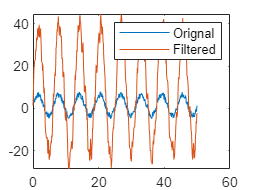

clf
t = linspace(0,50,500);
signal = 5*sin(t) + 3*rand(1,500);
plot(t,signal)
num = [1,2,3];
den = [1];
y = filter(num,den,signal);
hold on
plot(t,y)
hold off
legend("Orignal","Filtered")

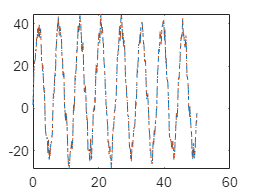

for i = 3:length(t)
    y_f(i) = signal(i) + 2*signal(i-1) + 3*signal(i-2);
end
plot(t,y,LineStyle="-.");
hold on 
plot(t,y_f,LineStyle=":")
hold off